EPFL Spacecraft Team - CHESS Mission Design

Arnaud Muller & Antoine Clout

Automn 2020

Import Data

if ~exist('PropagationResults')
    PropagationResults = importdata('PropagationResults.dat');
end
if ~exist('GroundStationData')
    GroundStationData = importdata('2020_GS_ECI_SBand.mat');
end

Extract wanted data

Dates = table2array(GroundStationData(:,1));
FirstEpoch = dateToEpoch(Dates(1));
LastEpoch = dateToEpoch(Dates(end));
GroundStationPosition = table2array(GroundStationData(:,2));

x_CHESS1_10 = PropagationResults(1:end-1,2);
y_CHESS1_10 = PropagationResults(1:end-1,3);
z_CHESS1_10 = PropagationResults(1:end-1,4);

x_CHESS2_10 = PropagationResults(1:end-1,6);
y_CHESS2_10 = PropagationResults(1:end-1,7);
z_CHESS2_10 = PropagationResults(1:end-1,8);

Propagate to 1s

x_CHESS1_1 = interp1(FirstEpoch:10:LastEpoch, x_CHESS1_10, FirstEpoch:1:LastEpoch)';
y_CHESS1_1 = interp1(FirstEpoch:10:LastEpoch, y_CHESS1_10, FirstEpoch:1:LastEpoch)';
z_CHESS1_1 = interp1(FirstEpoch:10:LastEpoch, z_CHESS1_10, FirstEpoch:1:LastEpoch)';

x_CHESS2_1 = interp1(FirstEpoch:10:LastEpoch, x_CHESS2_10, FirstEpoch:1:LastEpoch)';
y_CHESS2_1 = interp1(FirstEpoch:10:LastEpoch, y_CHESS2_10, FirstEpoch:1:LastEpoch)';
z_CHESS2_1 = interp1(FirstEpoch:10:LastEpoch, z_CHESS2_10, FirstEpoch:1:LastEpoch)';

State_CHESS1 = [x_CHESS1_1, y_CHESS1_1, z_CHESS1_1];
State_CHESS2 = [x_CHESS2_1, y_CHESS2_1, z_CHESS2_1];

Compute the elevation for each satellite at each epoch

if ~exist('Elevation_CHESS1')
    Elevation_CHESS1 = ComputeElevation(GroundStationPosition, State_CHESS1);
end
if ~exist('Elevation_CHESS2')
    Elevation_CHESS2 = ComputeElevation(GroundStationPosition, State_CHESS2);
end

Compute the communication windows

MinimumElevation = 10; % deg
Is_Communication_CHESS1 = Elevation_CHESS1 > MinimumElevation;
Is_Communication_CHESS2 = Elevation_CHESS2 > MinimumElevation;

compteur = 0;
Communication_Length_CHESS1 = zeros(length(Is_Communication_CHESS1),1);
for k=1:length(Is_Communication_CHESS1)
    if Is_Communication_CHESS1(k) == 0
        Communication_Length_CHESS1(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
Communication_Length_CHESS1(k) = compteur;
clear k compteur
Communication_Length_CHESS1=Communication_Length_CHESS1(Communication_Length_CHESS1 > 0);


compteur = 0;
Communication_Length_CHESS2 = zeros(length(Is_Communication_CHESS2),1);
for k=1:length(Is_Communication_CHESS2)
    if Is_Communication_CHESS2(k) == 0
        Communication_Length_CHESS2(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
Communication_Length_CHESS2(k) = compteur;
clear k compteur
Communication_Length_CHESS2=Communication_Length_CHESS2(Communication_Length_CHESS2 > 0);

Sorted_Communication_Length_CHESS1 = sort(Communication_Length_CHESS1);
Sorted_Communication_Length_CHESS2 = sort(Communication_Length_CHESS2);



BoxPlots

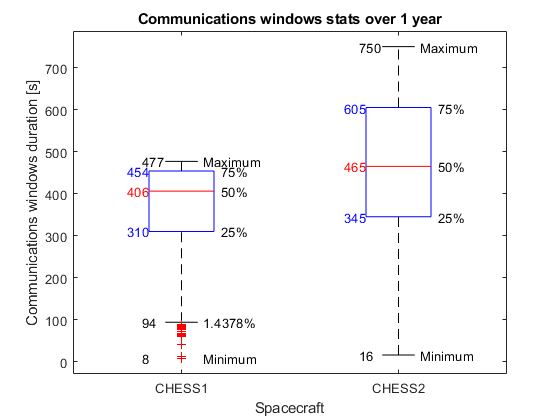

Quantiles_CHESS1 = quantile(Communication_Length_CHESS1,[0.25 0.5 0.75]);
Quantiles_CHESS2 = quantile(Communication_Length_CHESS2,[0.25 0.5 0.75]);

figure
boxplot([Communication_Length_CHESS1;Communication_Length_CHESS2],[repmat({'CHESS1'},length(Communication_Length_CHESS1),1);repmat({'CHESS2'},length(Communication_Length_CHESS2),1)])
xlabel('Spacecraft')
ylabel('Communications windows duration [s]')
title('Communications windows stats over 1 year')
text(0.75, Quantiles_CHESS1(1),num2str(Quantiles_CHESS1(1)),'Color',[0 0 1]);
text(0.75, Quantiles_CHESS1(2),num2str(Quantiles_CHESS1(2)),'Color',[1 0 0]);
text(0.75, Quantiles_CHESS1(3),num2str(Quantiles_CHESS1(3)),'Color',[0 0 1]);
text(1.75, Quantiles_CHESS2(1),num2str(Quantiles_CHESS2(1)),'Color',[0 0 1]);
text(1.75, Quantiles_CHESS2(2),num2str(Quantiles_CHESS2(2)),'Color',[1 0 0]);
text(1.75, Quantiles_CHESS2(3),num2str(Quantiles_CHESS2(3)),'Color',[0 0 1]);
text(1.18, Quantiles_CHESS1(1),'25%');
text(1.18, Quantiles_CHESS1(2),'50%');
text(1.18, Quantiles_CHESS1(3),'75%');
text(2.18, Quantiles_CHESS2(1),'25%');
text(2.18, Quantiles_CHESS2(2),'50%');
text(2.18, Quantiles_CHESS2(3),'75%');
text(0.82, min(Communication_Length_CHESS1),num2str(min(Communication_Length_CHESS1)));
text(1.10, min(Communication_Length_CHESS1),'Minimum');
text(1.82, min(Communication_Length_CHESS2),num2str(min(Communication_Length_CHESS2)));
text(2.10, min(Communication_Length_CHESS2),'Minimum');
text(0.82, max(Communication_Length_CHESS1),num2str(max(Communication_Length_CHESS1)));
text(1.10, max(Communication_Length_CHESS1),'Maximum');
text(1.82, max(Communication_Length_CHESS2),num2str(max(Communication_Length_CHESS2)));
text(2.10, max(Communication_Length_CHESS2),'Maximum');

min_outliner_CHESS1 = Quantiles_CHESS1(1)-1.5*iqr(Communication_Length_CHESS1);
if min(Communication_Length_CHESS1) < min_outliner_CHESS1
    index_outliner = find(Sorted_Communication_Length_CHESS1>=min_outliner_CHESS1,1,'first');
    percent_outliner = index_outliner/length(Communication_Length_CHESS1) *100;
    
    text(0.82, Sorted_Communication_Length_CHESS1(index_outliner),num2str(Sorted_Communication_Length_CHESS1(index_outliner)));
    text(1.10, Sorted_Communication_Length_CHESS1(index_outliner),append(num2str(percent_outliner),'%'));
end


max_outliner_CHESS1 = Quantiles_CHESS1(3)+1.5*iqr(Communication_Length_CHESS1);
if max(Communication_Length_CHESS1) > max_outliner_CHESS1
    index_outliner = find(Sorted_Communication_Length_CHESS2<=max_outliner_CHESS1,1,'last');
    percent_outliner = index_outliner/length(Communication_Length_CHESS1) *100;
    
    text(0.82, Sorted_Communication_Length_CHESS1(index_outliner),num2str(Sorted_Communication_Length_CHESS1(index_outliner)));
    text(1.10, Sorted_Communication_Length_CHESS1(index_outliner),append(num2str(percent_outliner),'%'));
end

min_outliner_CHESS2 = Quantiles_CHESS2(1)-1.5*iqr(Communication_Length_CHESS2);
if min(Communication_Length_CHESS2) < min_outliner_CHESS2
   index_outliner = find(Sorted_Communication_Length_CHESS2>=min_outliner_CHESS2,1,'first');
    percent_outliner = index_outliner/length(Communication_Length_CHESS2) *100;
    
    text(0.82, Sorted_Communication_Length_CHESS2(index_outliner),num2str(Sorted_Communication_Length_CHESS2(index_outliner)));
    text(1.10, Sorted_Communication_Length_CHESS2(index_outliner),append(num2str(percent_outliner),'%'));
end

max_outliner_CHESS2 = Quantiles_CHESS2(3)+1.5*iqr(Communication_Length_CHESS2);
if max(Communication_Length_CHESS2) > max_outliner_CHESS2
    index_outliner = find(Sorted_Communication_Length_CHESS2<=max_outliner_CHESS2,1,'last');
    percent_outliner = index_outliner/length(Communication_Length_CHESS2) *100;
    
    text(1.82, Sorted_Communication_Length_CHESS2(index_outliner),num2str(Sorted_Communication_Length_CHESS2(index_outliner)));
    text(2.10, Sorted_Communication_Length_CHESS2(index_outliner),append(num2str(percent_outliner),'%'));
end

Frequency of communication windows

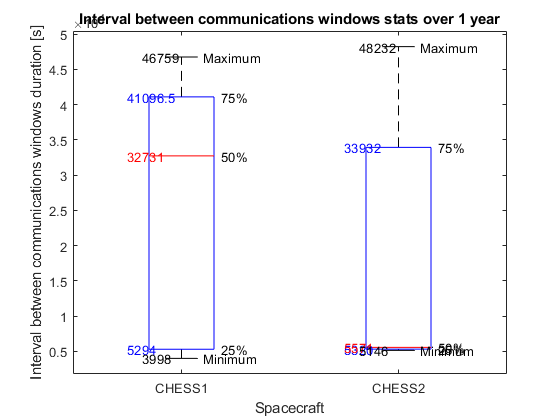

compteur = 0;
No_Communication_Length_CHESS1 = zeros(length(Is_Communication_CHESS1),1);
for k=1:length(Is_Communication_CHESS1)
    if Is_Communication_CHESS1(k) ~= 0
        No_Communication_Length_CHESS1(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
No_Communication_Length_CHESS1(k) = compteur;
clear k compteur
No_Communication_Length_CHESS1=No_Communication_Length_CHESS1(No_Communication_Length_CHESS1 > 0);

compteur = 0;
No_Communication_Length_CHESS2 = zeros(length(Is_Communication_CHESS2),1);
for k=1:length(Is_Communication_CHESS2)
    if Is_Communication_CHESS2(k) ~= 0
        No_Communication_Length_CHESS2(k) = compteur;
        compteur = 0;
    else
        compteur = compteur +1;    
    end
end
No_Communication_Length_CHESS2(k) = compteur;
clear k compteur
No_Communication_Length_CHESS2=No_Communication_Length_CHESS2(No_Communication_Length_CHESS2 > 0);

Sorted_No_Communication_Length_CHESS1 = sort(No_Communication_Length_CHESS1);
Sorted_No_Communication_Length_CHESS2 = sort(No_Communication_Length_CHESS2);

No_Quantiles_CHESS1 = quantile(No_Communication_Length_CHESS1,[0.25 0.5 0.75]);
No_Quantiles_CHESS2 = quantile(No_Communication_Length_CHESS2,[0.25 0.5 0.75]);

figure
boxplot([No_Communication_Length_CHESS1;No_Communication_Length_CHESS2],[repmat({'CHESS1'},length(No_Communication_Length_CHESS1),1);repmat({'CHESS2'},length(No_Communication_Length_CHESS2),1)])
xlabel('Spacecraft')
ylabel('Interval between communications windows duration [s]')
title('Interval between communications windows stats over 1 year')
text(0.75, No_Quantiles_CHESS1(1),num2str(No_Quantiles_CHESS1(1)),'Color',[0 0 1]);
text(0.75, No_Quantiles_CHESS1(2),num2str(No_Quantiles_CHESS1(2)),'Color',[1 0 0]);
text(0.75, No_Quantiles_CHESS1(3),num2str(No_Quantiles_CHESS1(3)),'Color',[0 0 1]);
text(1.75, No_Quantiles_CHESS2(1),num2str(No_Quantiles_CHESS2(1)),'Color',[0 0 1]);
text(1.75, No_Quantiles_CHESS2(2),num2str(No_Quantiles_CHESS2(2)),'Color',[1 0 0]);
text(1.75, No_Quantiles_CHESS2(3),num2str(No_Quantiles_CHESS2(3)),'Color',[0 0 1]);
text(1.18, No_Quantiles_CHESS1(1),'25%');
text(1.18, No_Quantiles_CHESS1(2),'50%');
text(1.18, No_Quantiles_CHESS1(3),'75%');
text(2.18, No_Quantiles_CHESS2(1),'25%');
text(2.18, No_Quantiles_CHESS2(2),'50%');
text(2.18, No_Quantiles_CHESS2(3),'75%');
text(0.82, min(No_Communication_Length_CHESS1),num2str(min(No_Communication_Length_CHESS1)));
text(1.10, min(No_Communication_Length_CHESS1),'Minimum');
text(1.82, min(No_Communication_Length_CHESS2),num2str(min(No_Communication_Length_CHESS2)));
text(2.10, min(No_Communication_Length_CHESS2),'Minimum');
text(0.82, max(No_Communication_Length_CHESS1),num2str(max(No_Communication_Length_CHESS1)));
text(1.10, max(No_Communication_Length_CHESS1),'Maximum');
text(1.82, max(No_Communication_Length_CHESS2),num2str(max(No_Communication_Length_CHESS2)));
text(2.10, max(No_Communication_Length_CHESS2),'Maximum');


min_outliner_CHESS1 = No_Quantiles_CHESS1(1)-1.5*iqr(No_Communication_Length_CHESS1);
if min(No_Communication_Length_CHESS1) < min_outliner_CHESS1
    index_outliner = find(Sorted_No_Communication_Length_CHESS1>=min_outliner_CHESS1,1,'first');
    percent_outliner = index_outliner/length(No_Communication_Length_CHESS1) *100;
    
    text(0.82, Sorted_No_Communication_Length_CHESS1(index_outliner),num2str(Sorted_No_Communication_Length_CHESS1(index_outliner)));
    text(1.10, Sorted_No_Communication_Length_CHESS1(index_outliner),append(num2str(percent_outliner),'%'));
end

max_outliner_CHESS1 = No_Quantiles_CHESS1(3)+1.5*iqr(No_Communication_Length_CHESS1);
if max(No_Communication_Length_CHESS1) > max_outliner_CHESS1
    index_outliner = find(Sorted_No_Communication_Length_CHESS2<=max_outliner_CHESS1,1,'last');
    percent_outliner = index_outliner/length(No_Communication_Length_CHESS1) *100;
    
    text(0.82, Sorted_No_Communication_Length_CHESS1(index_outliner),num2str(Sorted_No_Communication_Length_CHESS1(index_outliner)));
    text(1.10, Sorted_No_Communication_Length_CHESS1(index_outliner),append(num2str(percent_outliner),'%'));
end

min_outliner_CHESS2 = No_Quantiles_CHESS2(1)-1.5*iqr(No_Communication_Length_CHESS2);
if min(No_Communication_Length_CHESS2) < min_outliner_CHESS2
   index_outliner = find(Sorted_No_Communication_Length_CHESS2>=min_outliner_CHESS2,1,'first');
    percent_outliner = index_outliner/length(No_Communication_Length_CHESS2) *100;
    
    text(0.82, Sorted_No_Communication_Length_CHESS2(index_outliner),num2str(Sorted_No_Communication_Length_CHESS2(index_outliner)));
    text(1.10, Sorted_No_Communication_Length_CHESS2(index_outliner),append(num2str(percent_outliner),'%'));
end

max_outliner_CHESS2 = No_Quantiles_CHESS2(3)+1.5*iqr(No_Communication_Length_CHESS2);
if max(No_Communication_Length_CHESS2) > max_outliner_CHESS2
    index_outliner = find(Sorted_No_Communication_Length_CHESS2<=max_outliner_CHESS2,1,'last');
    percent_outliner = index_outliner/length(No_Communication_Length_CHESS2) *100;
    
    text(1.82, Sorted_No_Communication_Length_CHESS2(index_outliner),num2str(Sorted_No_Communication_Length_CHESS2(index_outliner)));
    text(2.10, Sorted_No_Communication_Length_CHESS2(index_outliner),append(num2str(percent_outliner),'%'));
end




